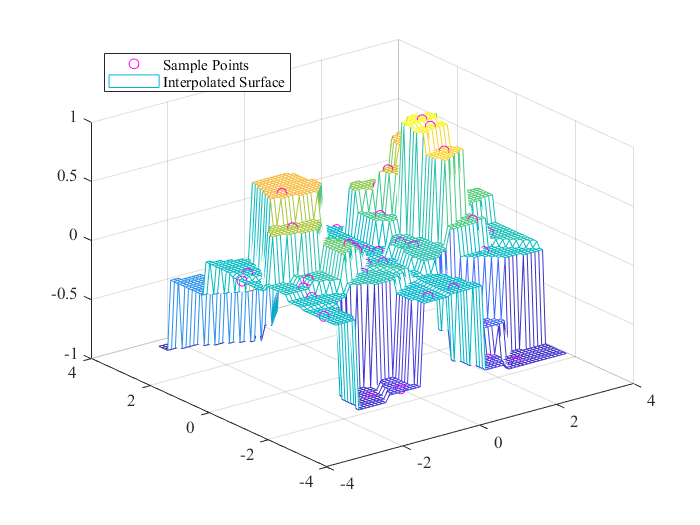

% 创建包含 50 个散点的样本数据集。这里有意使用较少的点数量，目的是为了突出插值方法之间的差异。
clear all
close all
%%
rng(10) % 使用种子10初始化随机数生成器
x = -3 + 6*rand(50,1);
y = -3 + 6*rand(50,1);
v = sin(x).^4 .* cos(y);
% 创建一个查询点网格。

[Xq,Yq] = meshgrid(-3:0.1:3);
% 使用 'nearest'、'linear'、'natural' 和 'cubic' 方法插入样本数据。绘制结果进行比较。
%vq = sin(Xq).^4 .* cos(Yq)
Vq = NNI(x,y,v,Xq,Yq);
plot3(x,y,v,'mo')
hold on
mesh(Xq,Yq,Vq) % 绘制插值曲面
% title('NNI')
legend('Sample Points','Interpolated Surface',...
    'Location','NorthWest')
set(gca, 'FontName','Times New Roman');
grid on

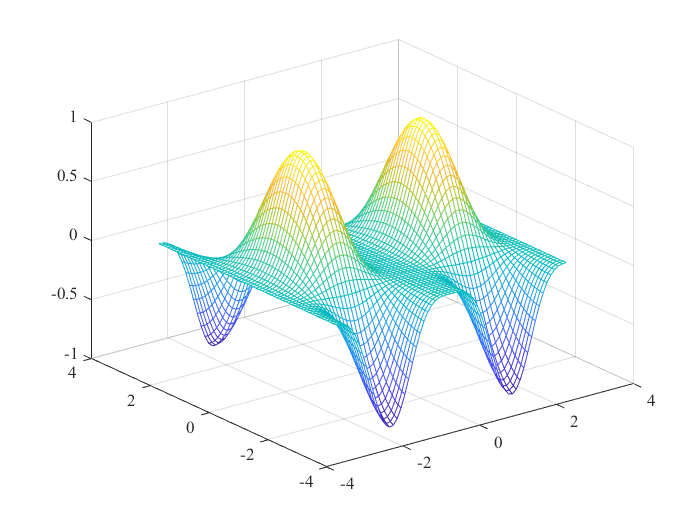



% 绘制原始曲面
figure
V = sin(Xq).^4 .* cos(Yq);
mesh(Xq,Yq,V)
%title('$z=\sin^{4}(x)\cos(y)$','interpreter','latex')
set(gca, 'FontName','Times New Roman');